## TOPIC 10: Revisiting arrays, pt. 3: improving computational efficiency

ENGR105, 10/6/20

### Logical arrays

#### Reminder: logical indexing and reshaping arrays

Last time, we talked about how logical arrays can be used to index vectors and matrices, incorporated into mathematical statements, and how arrays can be reshaped and restructured.

- We can perform **relational** and **logical** **operations on arrays** to create **logical vectors** for use in logical indexing or logical array math.

% Create a test arrays
a = 1:7

a =      1     2     3     4     5     6     7


% Use logical indexing to select all elements greater than 3
a(a>3)

ans =      4     5     6     7


% Use array math to set all elements that are NOT greater than 3 to 0.
a.*(a>3)

ans =      0     0     0     4     5     6     7


- There are useful built-in logical functions for evaluating if **none, some, or all** entries in a logical vector are `true` or `false`.

%b is a logical vector so only has 0 and 1
b = a > 1

b = 1×7 logical array
   1   1   1   1   1   1   1


% Evaluate if at least one entry is true
any(b)

ans = logical
   1


% Evaluate if all entries are true
all(b)

ans = logical
   1


% Evaluate if no entries are true
all(-b)

ans = logical
   1


- We can also **restructure** and **rotate** arrays using built-in functions.

% Reshape array of elements larger than 3 into a 2x2 array.
b = reshape(a(a>3),2,2)

b =      4     6
     5     7


% Rotate matrix 90 degrees ccw
rot90(b)

ans =      6     7
     4     5


% Reverse the rows
flipud(b)

ans =      5     7
     4     6


% Reverse the columns
fliplr(b)

ans =      6     4
     7     5


**Plotting example**. Assume we collected data points at many different time points and we wish to plot only a subset of these.

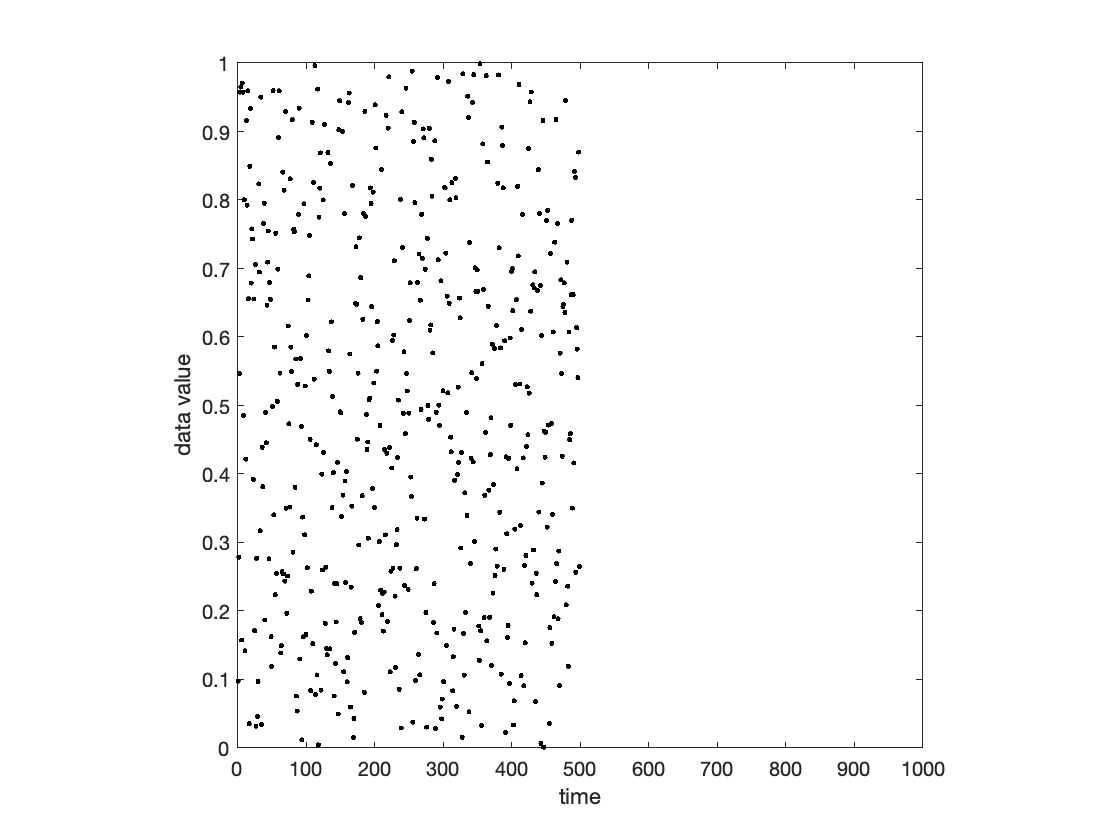

% Measured time points
t = 1:1000;
% Data points where each entry is the data point measured at the
% corresponding entry in the time vector.
dataPts = rand(1,length(t));

% Plot data
%plot for times less that 500
plot(t(t<500),dataPts(t<500),'k.')
axis square
ylim([0,1])         % y limit
xlim([0,length(t)]) % x limit
xlabel('time')      % data label for x axis
ylabel('data value')    % data label for y axis

- Q1: plot data from times** less than 500 -> logical indexing**

% Plot data at t < 500
plot(t(t<500),dataPts(t<500),'k.')

axis square
ylim([0,1])         % y limit
xlim([0,length(t)]) % x limit
xlabel('time')      % data label for x axis
ylabel('data value')    % data label for y axis

- Q2: plot data points with** values greater than 0.5 -> logical indexing**

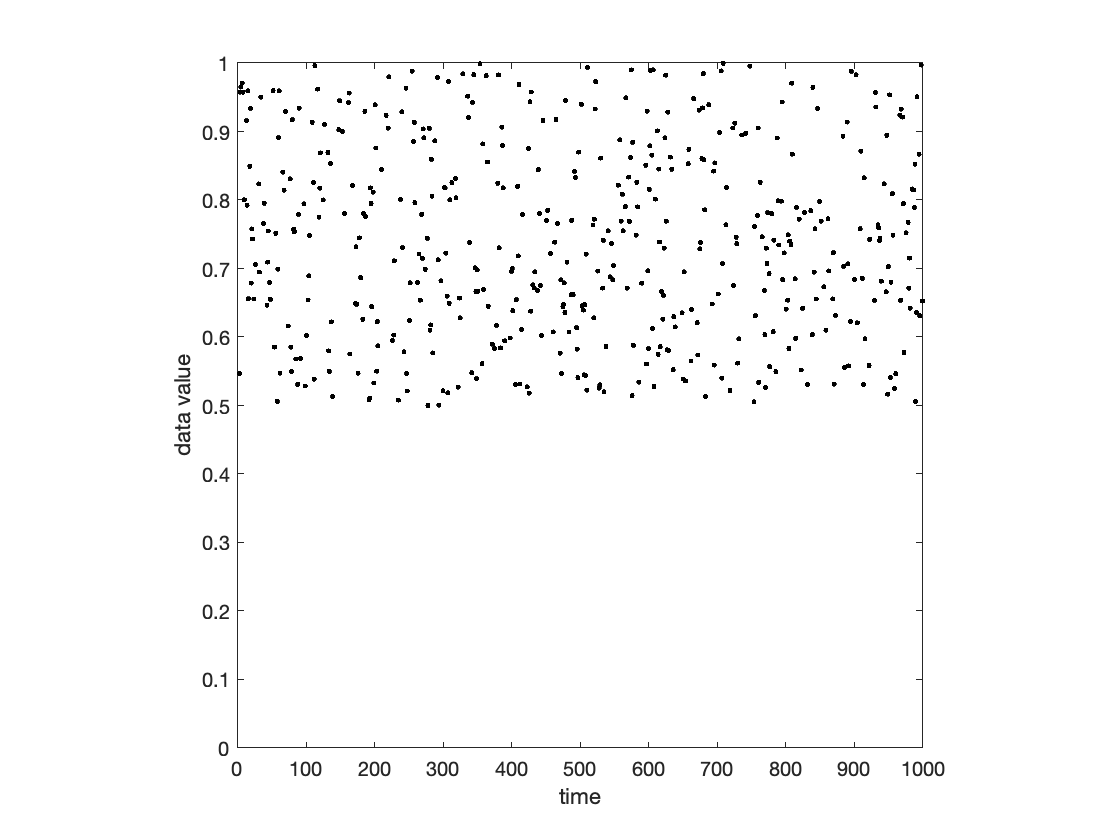

% Plot data with values greater than 0.5
plot(t(dataPts>0.5),dataPts(dataPts>0.5),'k.')

axis square
ylim([0,1])         % y limit
xlim([0,length(t)]) % x limit
xlabel('time')      % data label for x axis
ylabel('data value')    % data label for y axis

- Q3: plot data points with with values **greater than 0.7 set to 0 -> logical math**

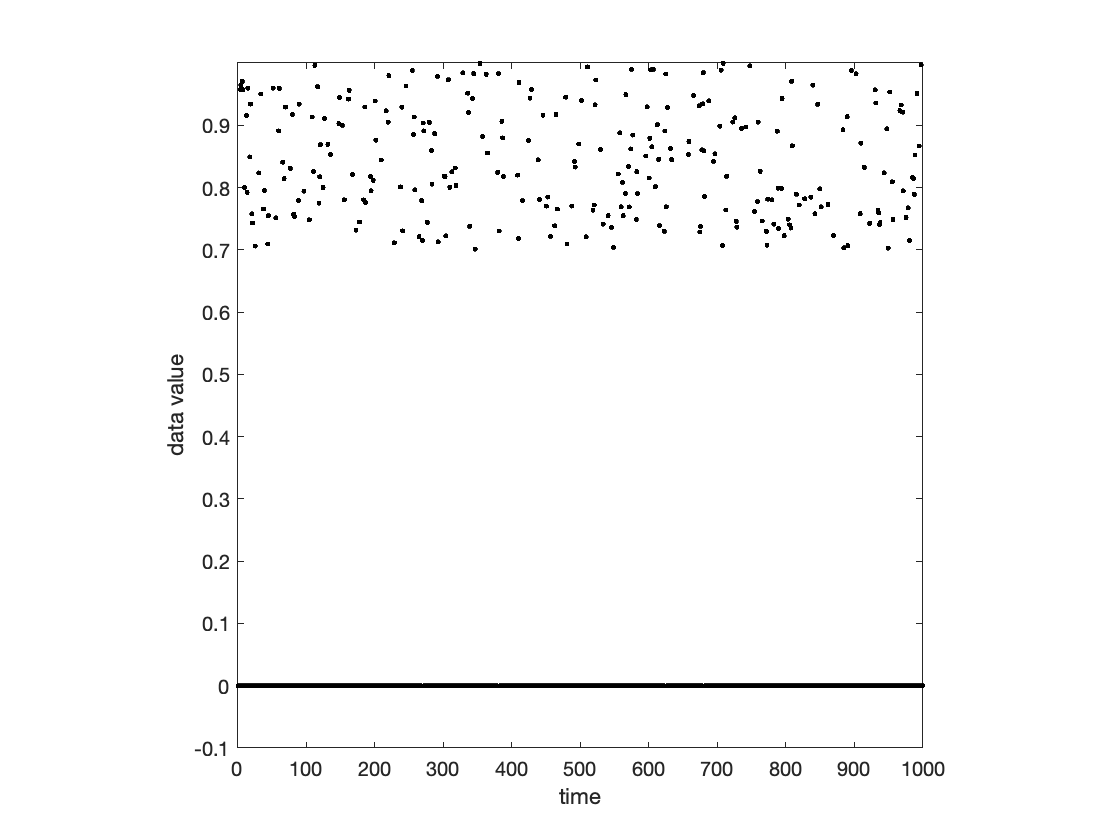

% Plot data with values greater than 0.7 set to 0

plot(t,dataPts.*(dataPts<=0.7),'k.')
axis square
ylim([-0.1,1])         % y limit
xlim([0,length(t)]) % x limit
xlabel('time')      % data label for x axis
ylabel('data value')    % data label for y axis

**NOTE**: in all of these example, note the agreement between the "x" and "y" inputs into the `plot()` function.

**Question**: produce the following piece-wise signal.

*Relevant UPenn Course: BE 301: Signals and Systems*

*Relevant UPenn Course: MEAM 321 Dynamic Systems and Control*

*Relevant UPenn Course: CBE 360 Chemical Process Control*

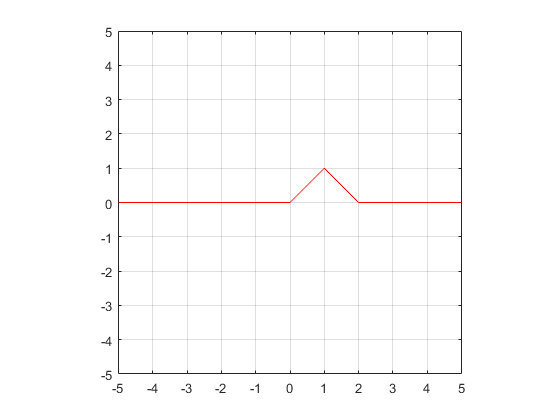

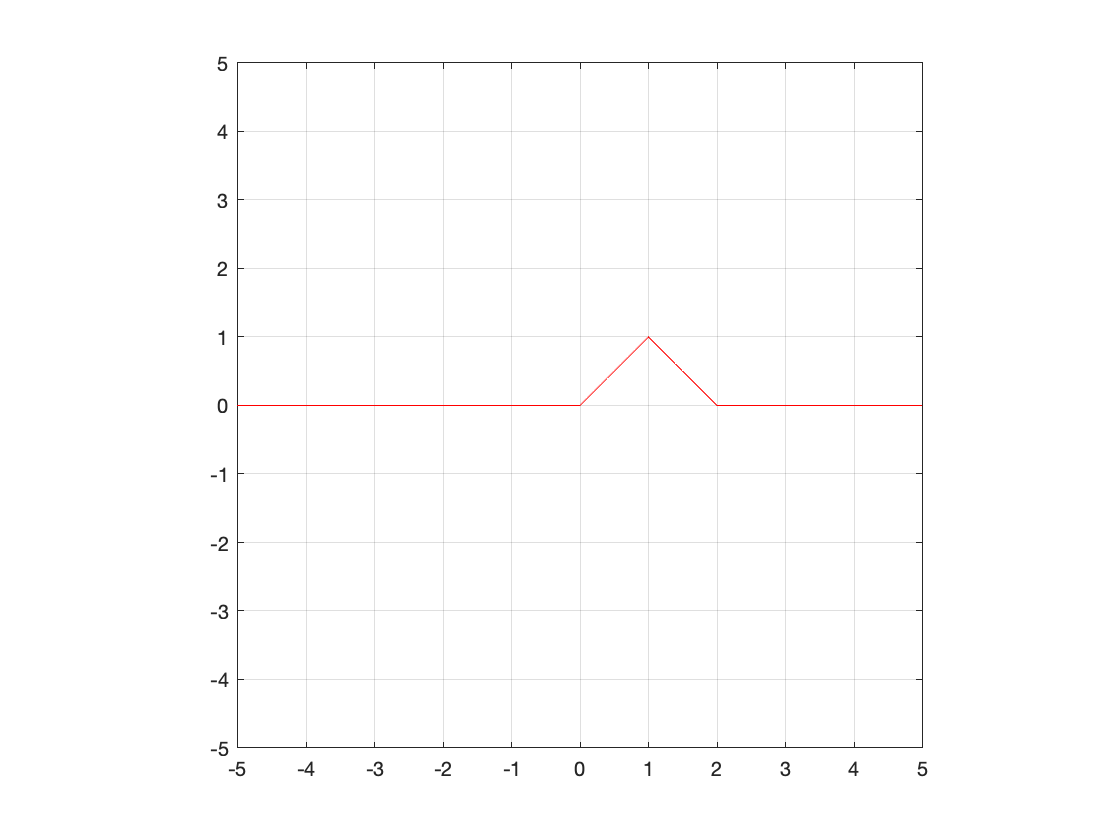

% Create the time vector
t = -5:0.1:5;
% Create the signal vector
x = t.*(t>=0).*(t<1) + (2-t).*(t>=1).*(t<2);

% Plot
plot(t,x,'r-')
axis square
ylim([-5,5])
xlim([-5,5])
grid on   % Display the grid
xticks(-5:5) % Explicitly define the x tick marks
yticks(-5:5)

#### Logical arrays vs. `if-else` statements

**Example #1**. The bonus for barkers selling peanuts at a baseball game is set at $0.02/pack if at least 100 packs were sold, $0.04/pack of at least 200 packs were sold, and $0.06/pack if at least 300 packs were sold. Calculate the bonus for four barkers who sold individually sold 57, 299, 161, and 429 packs of peanuts at a game.

% Create vector, each entry corresponds to a different seller's packs sold
packsSold = [57, 299, 161, 429];

So far, our strategy to accomplish this would be to create `if-else` statements nested in a loop.

bonus = zeros(1,4);
% Calculate bonuses.
for jj = 1:length(packsSold)
    
    % If >=100 and <200 packs sold
    if packsSold(jj)>=100 && packsSold(jj)<200
        bonus(jj) = .02*packsSold(jj);
    
    % If >=200 and <300 packs sold
    elseif packsSold(jj)>=200 && packsSold(jj)<300
        bonus(jj) = .04*packsSold(jj);
    
    % If >300 packs sold
    elseif packsSold(jj)>=300
        bonus(jj) = .06*packsSold(jj);
    end
end
disp(bonus)

         0   11.9600    3.2200   25.7400



A more concise (and easy to understand) way to calculate this would be to use logical array operations and math to perform all of the above calculations in one MATLAB statement.

% Calculate bonus using logical indexing
%make a logic based function that only multiplies agains thtings that were
%true 
bonus2 = ... 
    0.02*packsSold.*(packsSold>= 100 & packsSold<200) + ...
    0.04*packsSold.*(packsSold>= 200 & packsSold<300) + ...
    0.06*packsSold.*(packsSold>= 300);
disp(bonus2)

  Columns 1 through 10

   27.3600   11.0800         0   23.8200   28.7400    3.6800         0         0   20.1600   11.6400

  Columns 11 through 20

   29.4600    3.0400         0   10.2400   22.7400   22.4400   18.5400    9.9600         0    3.7000

  Columns 21 through 30

    8.3600   22.5000   27.0600         0    2.7800         0   23.8200   22.1400   25.6800   24.3000

  Columns 31 through 40

   11.0000    3.3600    2.2000   22.7400    9.6000         0    3.9800   29.1600         0         0

  Columns 41 through 50

         0   11.8400   26.5200   28.1400    8.7200    3.6600   23.4600   23.7000    9.9200         0

  Columns 51 through 60

   20.5200   22.0800    3.5800    3.0200    3.7800   22.5600    8.4800   20.8800   28.9200   27.4800

  Columns 61 through 70

    3.7000   29.3400   18.9000   22.9800   25.9800    9.8400   28.8600   24.9000         0   22.6800

  Columns 71 through 80

   28.1400   23.8800    9.4400         0   11.8800   26.5200    3.5200   27.7200   20.1

In this example, we add together three logical vectors (corresponding to each of the bonus conditions) that are multiplied by the corresponding dollar bonus.

**Example #2**. Employees of a business are paid at a rate of $19/hr and receive overtime (time and a half) above 40 hours/week. Calculate the pay for employees who worked 45, 21, 19, 61, and 39 hours last week.

%define verctor containing employee hours
employeeHours = [45, 21, 19, 61, 39];
%calculate pay in one statement 
eployeePay = 10*employeeHours + 19*0.5*(employeeHours-40).*(employeeHours>40)

eployeePay =   497.5000  210.0000  190.0000  809.5000  390.0000


%at the end there is a logical that only multiplies if there is more than
%40 hours 






**Example #3**. Instead of four people selling peanuts, you have N barkers selling packs of peanuts at sporting events in your multi-national event management corporation. Compare the computational time using if-else statements and logical arrays for determining the bonus pay each barker should receive, as a function of N, the number of barkers. Assume employees can sell 1 - 500 packs at a given event.

% Vector containing different numbers of barkers. We will calculate the
% time to calculate the bonus for increasing N using if-else vs. logical arrays
N = round(logspace(1,6,100));

% Preallocate vectors to store computational time
t_ifElse = zeros(1,length(N));
t_logicalMath = zeros(1,length(N));

% Calculate computational time for vector of different numbers of barkers
for k = 1:length(N)
    
    % Generate vector containing packs sold. Each entry corresponds to the
    % packs sold by a different employee.
    packsSold = randi(500,[1,N(k)]);
    
    % Calculate time using conditional statement
    tic;
    % Preallocate bonus array
    bonus1 = zeros(1,length(packsSold));
    
    % Calculate bonus received for each employee
    for jj = 1:length(packsSold)
    
        % If >=100 and <200 packs sold
        if packsSold(jj)>=100 && packsSold(jj)<200
            bonus(jj) = .02*packsSold(jj);
        
        % If >=200 and <300 packs sold
        elseif packsSold(jj)>=200 && packsSold(jj)<300
            bonus(jj) = .04*packsSold(jj);
        
        % If >300 packs sold
        elseif packsSold(jj)>=300
            bonus(jj) = .06*packsSold(jj);
        end
    end
    t_ifElse(k) = toc;
    
    
    % Calculate time using logical array operations and math
    tic;
    % Calculate bonus in one statement
    bonus2 = ...
        0.02*packsSold.*(packsSold>=100 & packsSold<200) + ...
        0.04*packsSold.*(packsSold>=200 & packsSold<300) + ...
        0.06*packsSold.*(packsSold>=300);
    t_logicalMath(k) = toc;
end

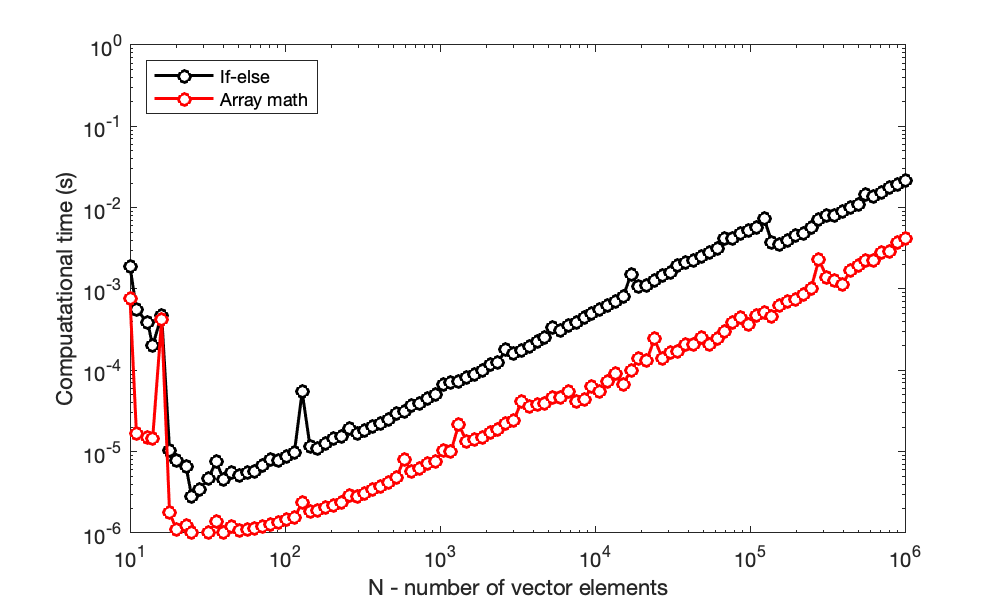

% Define dimensions of plot
figure('Position',[0,0,500,300]);
% Plot the functions
plot(N,t_ifElse,'ko-',N,t_logicalMath,'ro-','LineWidth',1.5,'MarkerFaceColor','auto')
% Graphical parameters
set(gca, 'XScale', 'log')   % "log" axes - x
set(gca, 'YScale', 'log')   % "log" axes - y
set(gca,'XMinorTick','on')
xlim([10^1,10^6]);  % range of x values on plot
ylim([10^-6,10^0]); % range of y values on plot
xlabel('N - number of vector elements');
ylabel('Compuatational time (s)');
legend('If-else','Array math','Location','northwest')

**Takeaway**: creating simple statements using logical arrays can be more efficient and easier to understand.

#### Always preallocate arrays

As we saw with vectors, preallocation is the process of creating an array of the final size (usually padded with zeros) before modifying each element of the array.** Consider the computational time associated with creating an NxN multiplication table** using for loops for different numbers of N.

That is, what we want to create:

            
$$\left\lbrack \begin{array}{cccccc}
1 & 2 & 3 & 4 & 5 & \cdots \\
2 & 4 & 6 & 8 & 10 & \cdots \\
3 & 6 & 9 & 12 & 15 & \cdots \\
4 & 8 & 12 & 16 & 20 & \cdots \\
5 & 10 & 15 & 20 & 25 & \cdots \\
\vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \ddots 
\end{array}\right\rbrack$$


% Determine range of N
N = logspace(0,3,4);

% Preallocate vectors to store computational time
t_no = zeros(length(N),1);
t_yes = zeros(length(N),1);

% For each number of elements considered
for k = 1:length(N)
    
    % Calculate time without preallocation
    tic;
    % For each row
    for jj = 1:N(k)
        % For each column
        for mm = 1:N(k)
            % Each entry is the produce of the rows and columns of the
            % multiplication table
            multTable(jj,mm) = jj*mm;
        end
    end
    t_no(k) = toc;
    
    % Calculate time without preallocation
    tic;
    % Preallocate array
    multTable = zeros(N(k),N(k));
    
    % For each row
    for jj = 1:N(k)
        % For each column
        for mm = 1:N(k)
            % Each entry is the produce of the rows and columns of the
            % multiplication table
            multTable(jj,mm) = jj*mm;
        end
    end
    t_yes(k) = toc;
    
    % Delete multiplication table so that it can be created from scratch on
    % the next loop
    clear multTable 
end

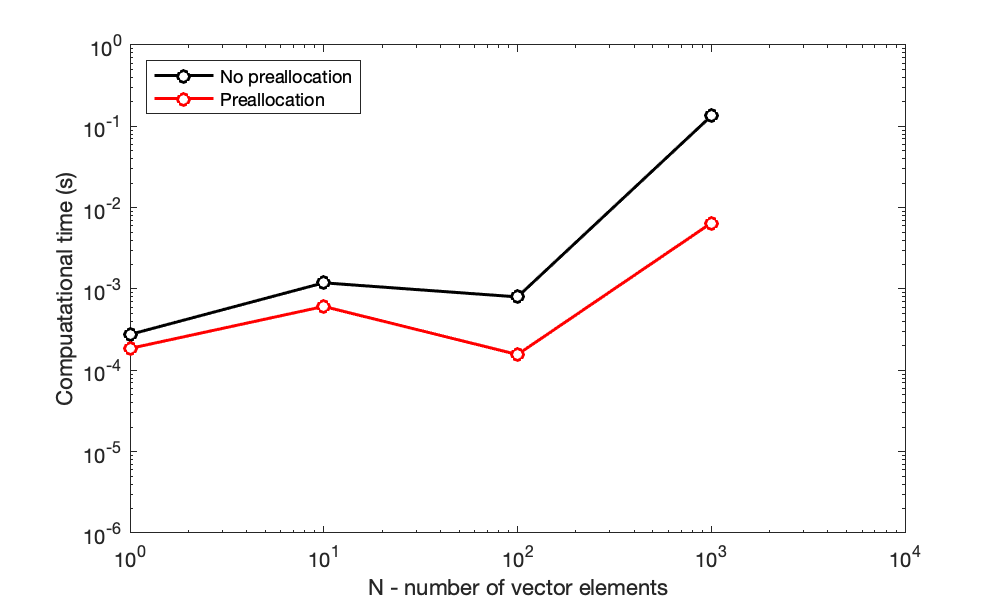

% Define dimensions of plot
figure('Position',[0,0,500,300]);
% Plot the functions
plot(N,t_no,'ko-',N,t_yes,'ro-','LineWidth',1.5,'MarkerFaceColor','auto')
% Graphical parameters
set(gca, 'XScale', 'log')   % "log" axes - x
set(gca, 'YScale', 'log')   % "log" axes - y
set(gca,'XMinorTick','on')
xlim([10^0,10^4]);  % range of x values on plot
ylim([10^-6,10^0]); % range of y values on plot
xlabel('N - number of vector elements');
ylabel('Compuatational time (s)');
legend('No preallocation','Preallocation','Location','northwest')

**Side note**: the above multiplication table can be create **much more efficiently** using **matrix multiplication **instead of nested for loops.

multTable = (1:10)'*(1:10)

multTable =      1     2     3     4     5     6     7     8     9    10
     2     4     6     8    10    12    14    16    18    20
     3     6     9    12    15    18    21    24    27    30
     4     8    12    16    20    24    28    32    36    40
     5    10    15    20    25    30    35    40    45    50
     6    12    18    24    30    36    42    48    54    60
     7    14    21    28    35    42    49    56    63    70
     8    16    24    32    40    48    56    64    72    80
     9    18    27    36    45    54    63    72    81    90
    10    20    30    40    50    60    70    80    90   100


#### Sparse arrays

Sparse matrices -- large arrays with few nonzero entries -- are encountered in a broad set of engineering disciplines, with applications including solving PDEs, search algorithms, atomistics, and FEA. 

        
$$\left\lbrack \begin{array}{ccccc}
0 & 0 & 0 & 0 & 0\\
0 & 0\ldotp 5 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 2\ldotp 8 & 0\\
3 & 0 & 0 & 0 & 0
\end{array}\right\rbrack$$


Consider a sparse matrix of dimensions 1000 x 2000 elements - that correlates to 2 million data points. Assume that this matrix contains non-zero values at the following indices:

- (row 3, column 4) = 15

- (row 100, column 1500) = 5

- (row 1000, column 2000) = 9

This matrix may be established using a conventional matrix indexing:

A = zeros(1000,2000);
A(3,4) = 15;
A(100,1500) = 5;
A(1000,2000) = 9;

Sparse matrices can be stored efficiently as a matrix of 0’s with nonzero values stored by their row, column, and value – this can save significant memory space. In the above example, this matrix could also be established using a sparse matrix syntax:

B = sparse([3,100,1000],...
    [4,1500,2000],...
    [15,5,9],1000,2000);

Or, the original non-sparse matrix `A` could also be converted to a sparse matrix:

B = sparse(A);

  Name         Size                 Bytes  Class     Attributes

  A         1000x2000            16000000  double              
  B         1000x2000               16056  double    sparse    



**The sparse matrix offers considerable savings for memory**. Information about each variable can be depicted using the `whos` command.

whos A B

In this case, variable A requires 16 MB of memory to create the **full matrix**, whereas variable B (**the sparse array**) only requires 16 kB! Dramatic savings in memory can be observed when most of the elements are zero.

**At what number of nonzero elements do sparse matrices lose this advantage?** Let's plot the memory associated with a matrix variable for different numbers of nonzero elements in a 100x100 matrix.

% Define a matrix intially with all zeros
A = zeros(100,100);

% Preallocate vector to store memory
mem_Full = zeros(1,numel(A));
mem_Sparse = zeros(1,numel(A));

% Repeat for all elements
for k = 1:numel(A)
    A(k) = randi(5);
    
    A_sparse = sparse(A);
    
    matrixInfo = whos('A','A_sparse');
    mem_Full(k) = matrixInfo(1).bytes;
    mem_Sparse(k) = matrixInfo(2).bytes;
end

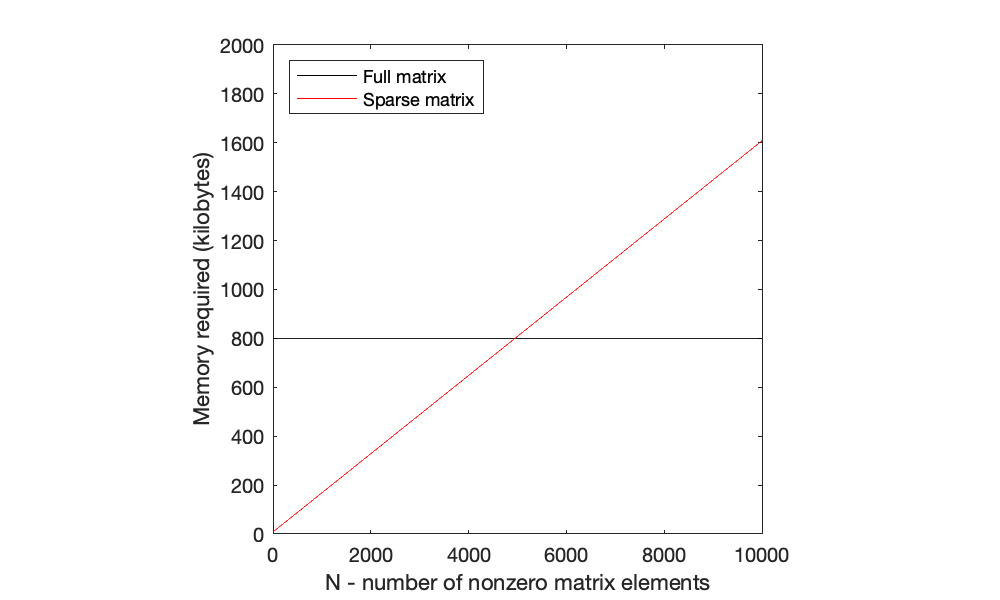

% Plot the functions
plot(1:numel(A),mem_Full/100,'k-',1:numel(A),mem_Sparse/100,'r-')

% Graphical parameters
axis square
xlim([0,10^4]);  % range of x values on plot
ylim([0,2*10^3]); % range of y values on plot
xlabel('N - number of nonzero matrix elements');

ylabel('Memory required (kilobytes)');
legend('Full matrix','Sparse matrix','Location','northwest')

In addtion to memory, a similar dramatic savings in computational time when working with sparse arrays can be observed by using `tic` and `toc`, as we have done previously. 

**Note**: if you need to convert a sparse matrix to a full matrix, this can be accomplished using `full()`.